clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater_newmonkey';
cd(workingpath);

files=dir('*side.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-9),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201112_side.csv


   24.1691  103.7750  183.3810   83.3684  103.6812  123.9940



吲哚_R_20201110_side.csv


   22.5979   91.4750  160.3520   87.8773  103.7917  119.7060



异戊酸_L_20201109_side.csv


   37.3760   80.3040  123.2320   99.3369  108.5750  117.8130



异戊酸_R_20201106_side.csv


   23.6995   91.5392  159.3790   89.8900  104.6115  119.3330



白桃_L_20201103_side.csv


   21.6836   92.4353  163.1870   84.2773  103.1001  121.9230



白桃_R_20201102_side.csv


   25.2768   85.7194  146.1620   86.1642  102.0641  117.9640



香蕉_L_20201105_side.csv


   90.8270  108.0140  125.2010   91.7951   95.3502   98.9053



香蕉_R_20201104_side.csv


   21.5329  113.3140  205.0950   65.1311   96.3986  127.6660



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-20201112


   100   100



pvalue = 0

st =     chi2stat: 1.4602e+04
          df: 1
       edges: [0 100 200]
           O: [65185 28248]
           E: [4.6716e+04 4.6716e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5025e+04
          df: 1
       edges: [0 100 200]
           O: [63969 26999]
           E: [45484 45484]


    80   120



pvalue = 0

st =     chi2stat: 1.7394e+04
          df: 1
       edges: [0 100 200]
           O: [63060 24119]
           E: [4.3590e+04 4.3590e+04]


吲哚-R-20201110


   100   100



pvalue = 0

st =     chi2stat: 1.4222e+04
          df: 1
       edges: [0 100 200]
           O: [63275 27370]
           E: [4.5322e+04 4.5322e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.6484e+04
          df: 1
       edges: [0 100 200]
           O: [63088 24985]
           E: [4.4036e+04 4.4036e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.8159e+04
          df: 1
       edges: [0 100 200]
           O: [62009 22772]
           E: [4.2390e+04 4.2390e+04]


异戊酸-L-20201109


   100   100



pvalue = 0

st =     chi2stat: 1.2576e+04
          df: 1
       edges: [0 100 200]
           O: [62130 28390]
           E: [45260 45260]


    90   110



pvalue = 0

st =     chi2stat: 1.5072e+04
          df: 1
       edges: [0 100 200]
           O: [62130 25738]
           E: [43934 43934]


    80   120



pvalue = 0

st =     chi2stat: 1.7175e+04
          df: 1
       edges: [0 100 200]
           O: [62089 23703]
           E: [42896 42896]


异戊酸-R-20201106


   100   100



pvalue = 0

st =     chi2stat: 1.3716e+04
          df: 1
       edges: [0 100 200]
           O: [64293 28598]
           E: [4.6446e+04 4.6446e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5702e+04
          df: 1
       edges: [0 100 200]
           O: [64105 26406]
           E: [4.5256e+04 4.5256e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.6653e+04
          df: 1
       edges: [0 100 200]
           O: [62815 24650]
           E: [4.3732e+04 4.3732e+04]


白桃-L-20201103


   100   100



pvalue = 0

st =     chi2stat: 4.2011e+03
          df: 1
       edges: [0 100 200]
           O: [55516 35917]
           E: [4.5716e+04 4.5716e+04]


    90   110



pvalue = 0

st =     chi2stat: 5.8364e+03
          df: 1
       edges: [0 100 200]
           O: [55100 32490]
           E: [43795 43795]


    80   120



pvalue = 0

st =     chi2stat: 7.8384e+03
          df: 1
       edges: [0 100 200]
           O: [53805 28418]
           E: [4.1112e+04 4.1112e+04]


白桃-R-20201102


   100   100



pvalue = 7.6011e-229

st =     chi2stat: 1.0431e+03
          df: 1
       edges: [0 100 200]
           O: [51242 41411]
           E: [4.6326e+04 4.6326e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5532e+03
          df: 1
       edges: [0 100 200]
           O: [51242 39378]
           E: [45310 45310]


    80   120



pvalue = 0

st =     chi2stat: 2.2731e+03
          df: 1
       edges: [0 100 200]
           O: [50627 36550]
           E: [4.3588e+04 4.3588e+04]


香蕉-L-20201105


   100   100



pvalue = 0

st =     chi2stat: 1.9061e+04
          df: 1
       edges: [0 100 200]
           O: [68058 25768]
           E: [46913 46913]


    90   110



pvalue = 0

st =     chi2stat: 1.9856e+04
          df: 1
       edges: [0 100 200]
           O: [66218 23914]
           E: [45066 45066]


    80   120



pvalue = 0

st =     chi2stat: 2.0163e+04
          df: 1
       edges: [0 100 200]
           O: [64730 22735]
           E: [4.3732e+04 4.3732e+04]


香蕉-R-20201104


   100   100



pvalue = 0

st =     chi2stat: 7.4811e+03
          df: 1
       edges: [0 100 200]
           O: [58085 32109]
           E: [45097 45097]


    90   110



pvalue = 0

st =     chi2stat: 8.4453e+03
          df: 1
       edges: [0 100 200]
           O: [56982 29895]
           E: [4.3438e+04 4.3438e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.1207e+04
          df: 1
       edges: [0 100 200]
           O: [54544 24736]
           E: [39640 39640]


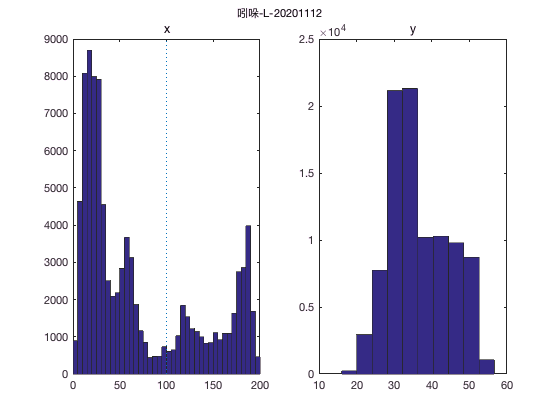

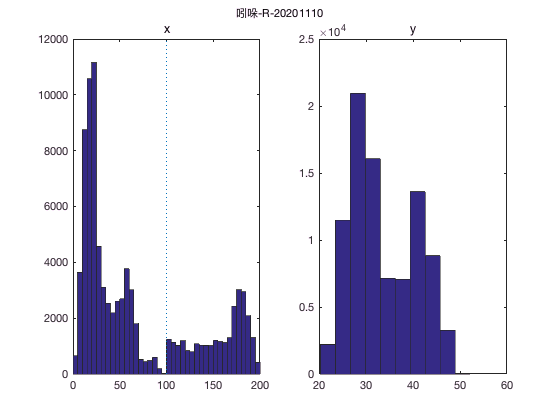

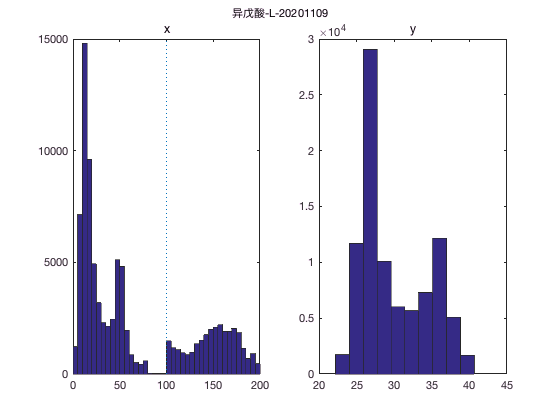

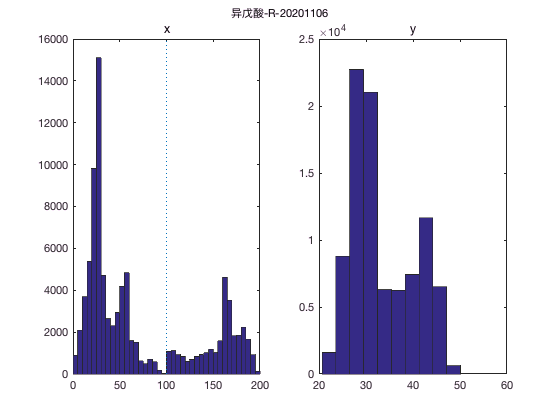

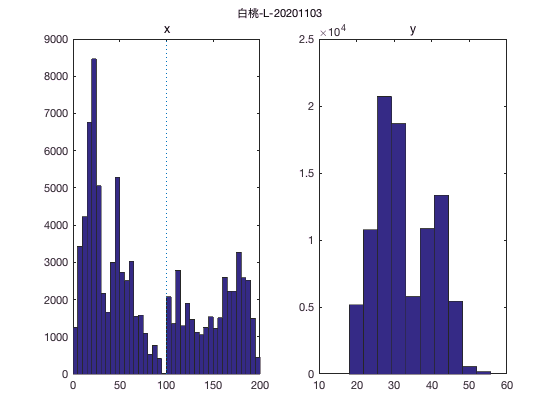

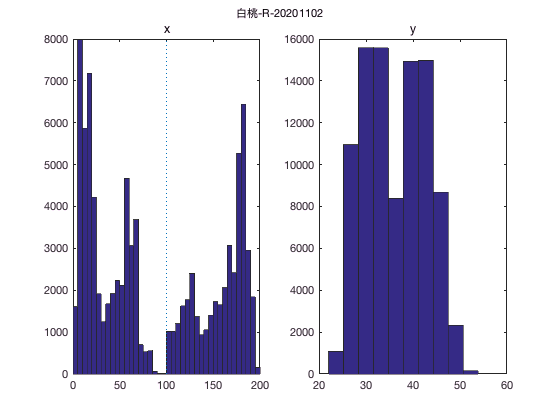

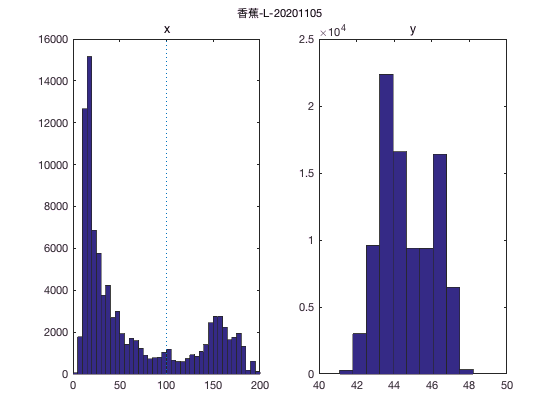

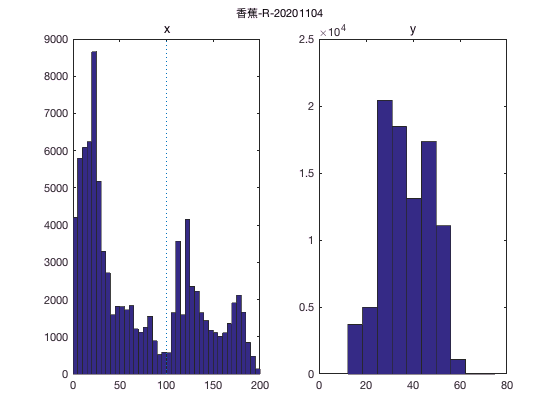

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 7.8286e+04
          df: 1
       edges: [0 100 200]
           O: [487784 247811]
           E: [3.6780e+05 3.6780e+05]


    90   110



pvalue = 0

st =     chi2stat: 8.9840e+04
          df: 1
       edges: [0 100 200]
           O: [482834 229805]
           E: [3.5632e+05 3.5632e+05]


    80   120



pvalue = 0

st =     chi2stat: 1.0384e+05
          df: 1
       edges: [0 100 200]
           O: [473679 207683]
           E: [340681 340681]


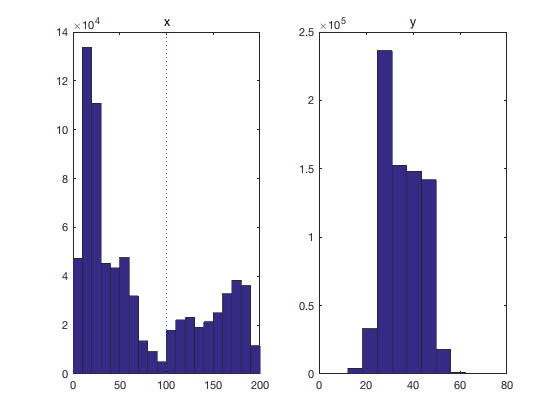


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

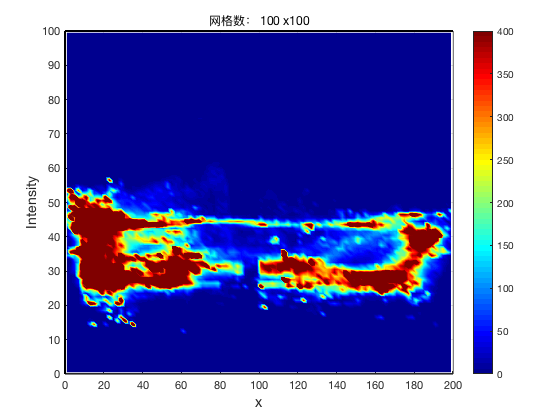

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 36.807535 秒。


## 合并odor两个条件(0-30)

吲哚-L-20201112


   100   100



pvalue = 0

st =     chi2stat: 1.1763e+04
          df: 1
       edges: [0 100 200]
           O: [44302 45698]
           E: [5.9680e+04 3.0320e+04]


异戊酸-L-20201109


   100   100



pvalue = 0

st =     chi2stat: 1.1233e+04
          df: 1
       edges: [0 100 200]
           O: [44652 45348]
           E: [5.9680e+04 3.0320e+04]


白桃-L-20201103


   100   100



pvalue = 0

st =     chi2stat: 3.4739e+03
          df: 1
       edges: [0 100 200]
           O: [51323 38677]
           E: [5.9680e+04 3.0320e+04]


香蕉-L-20201105


   100   100



pvalue = 0

st =     chi2stat: 2.7183e+03
          df: 1
       edges: [0 100 200]
           O: [52287 37712]
           E: [5.9680e+04 3.0319e+04]


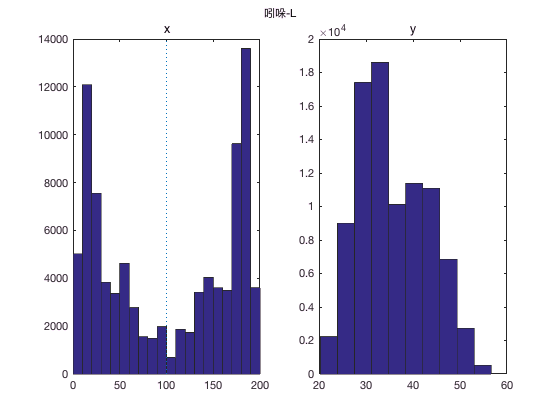

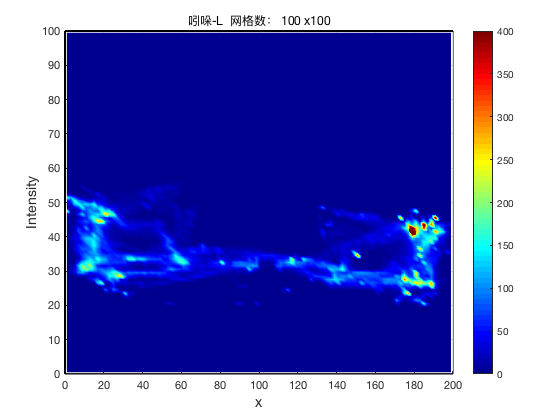

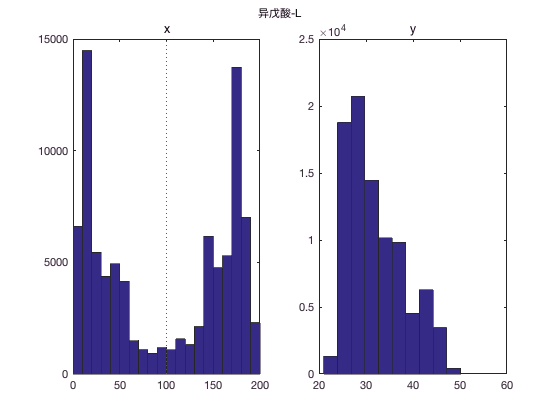

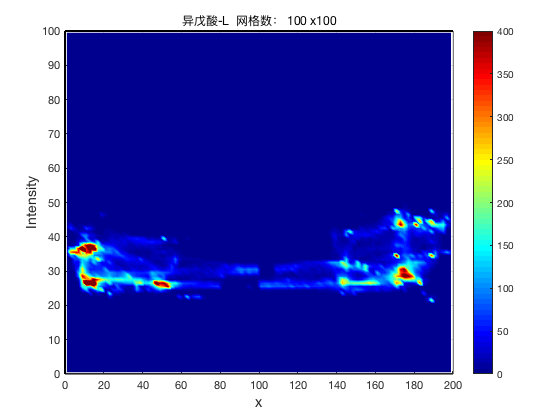

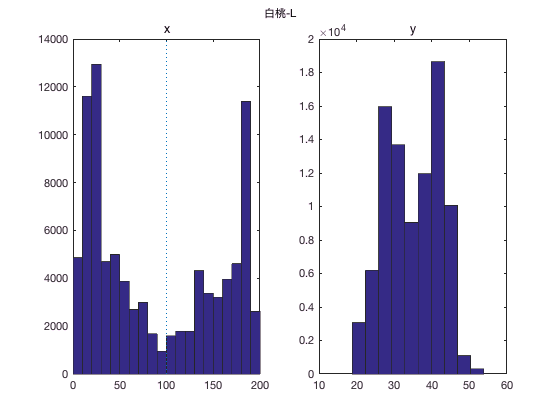

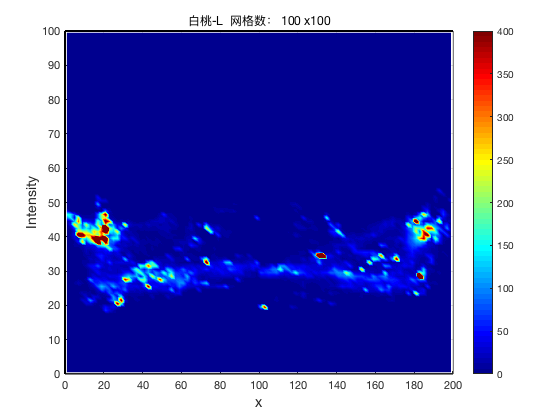

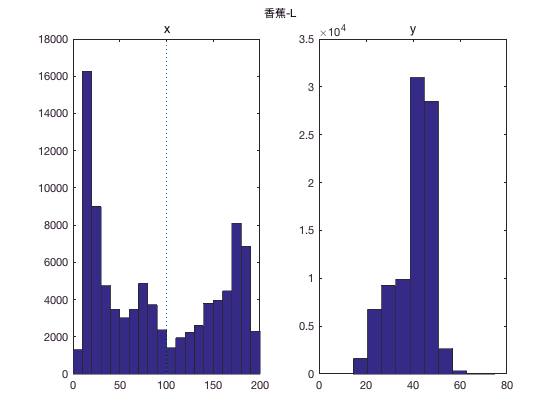

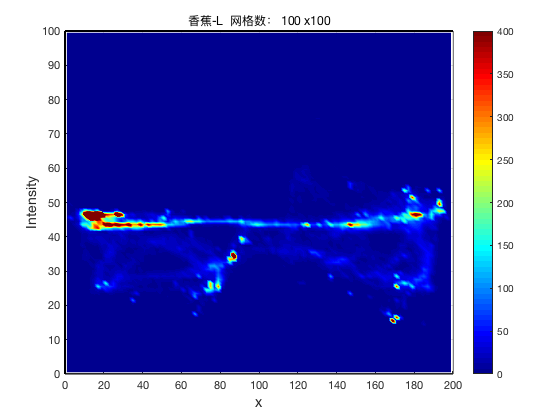

tic;
interval=10;
timeint1=0;%start minute
timeint2=30;%stop minute
p1=timeint1*60*1000/40+1;
p2=timeint2*60*1000/40;

for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
    % chisq test
    disp(conditions{odor-1})
    for i=0%:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 36.972209 秒。


## 合并odor两个条件(30-60)

吲哚-L-20201112


   100   100



pvalue = 0

st =     chi2stat: 1.0380e+04
          df: 1
       edges: [0 100 200]
           O: [45234 44766]
           E: [5.9680e+04 3.0320e+04]


异戊酸-L-20201109


   100   100



pvalue = 0

st =     chi2stat: 1.0571e+04
          df: 1
       edges: [0 100 200]
           O: [45102 44898]
           E: [5.9680e+04 3.0320e+04]


白桃-L-20201103


   100   100



pvalue = 0

st =     chi2stat: 1.3267e+04
          df: 1
       edges: [0 100 200]
           O: [43348 46652]
           E: [5.9680e+04 3.0320e+04]


香蕉-L-20201105


   100   100



pvalue = 0

st =     chi2stat: 9.8720e+03
          df: 1
       edges: [0 100 200]
           O: [45592 44408]
           E: [5.9680e+04 3.0320e+04]


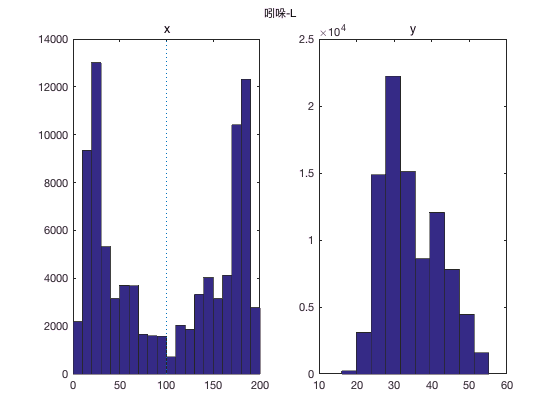

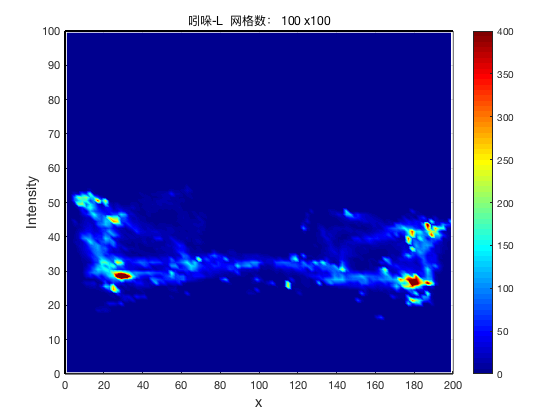

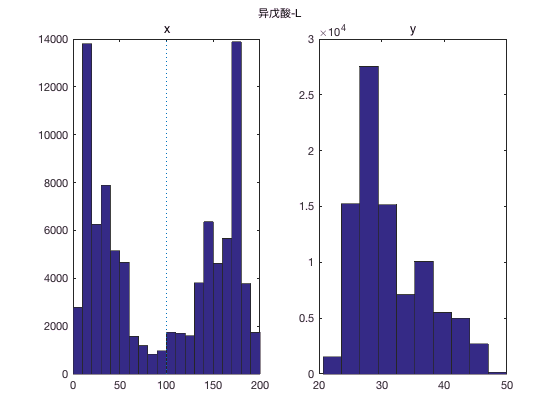

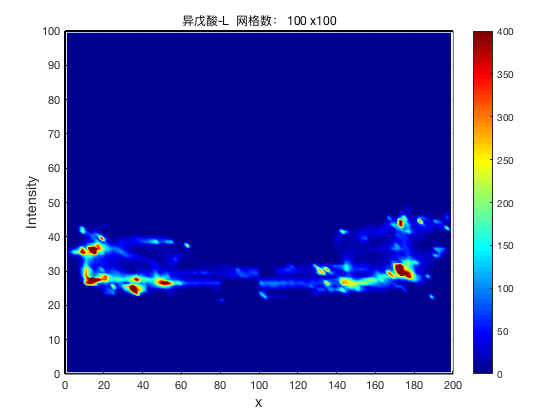

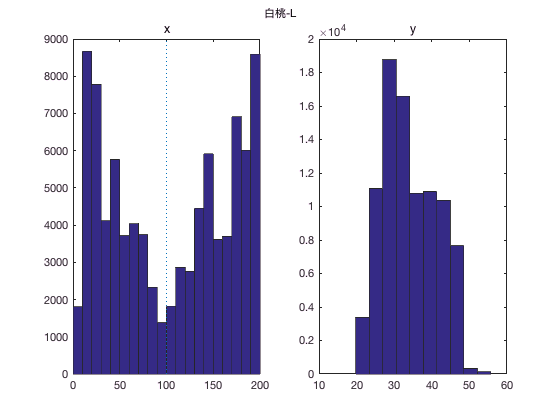

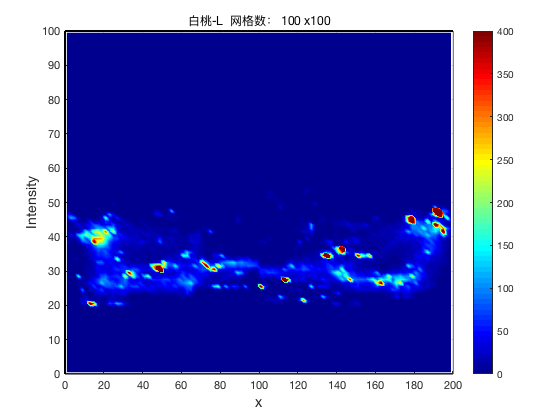

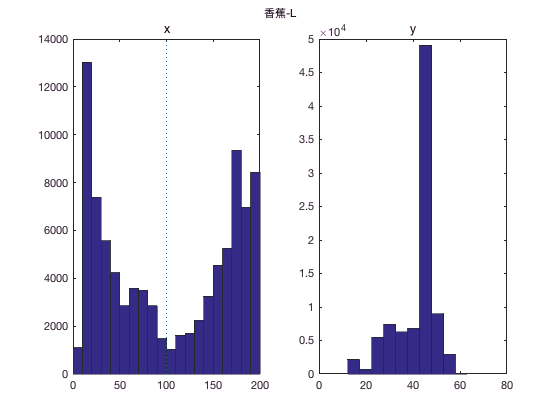

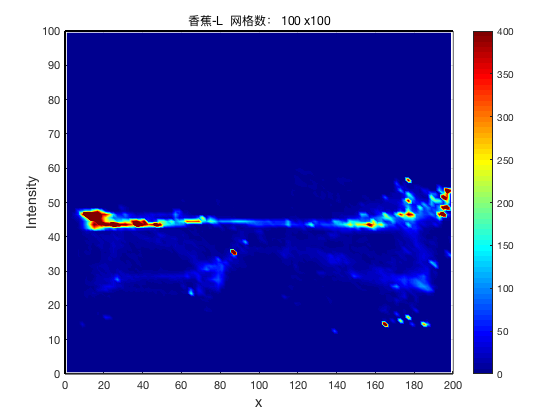

tic;
interval=10;
timeint1=30;%start minute
timeint2=60;%stop minute
p1=timeint1*60*1000/40+1;
p2=timeint2*60*1000/40;

for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
    % chisq test
    disp(conditions{odor-1})
    for i=0%:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 36.521377 秒。


## 合并odor两个条件的only two side（0-30）

   100   100



pvalue = 7.5116e-16

st =     chi2stat: 64.9943
          df: 1
       edges: [0 100 200]
           O: [31866 33934]
           E: [32900 32900]


   100   100



pvalue = 1.9841e-25

st =     chi2stat: 108.6017
          df: 1
       edges: [0 100 200]
           O: [35832 33096]
           E: [34464 34464]


   100   100



pvalue = 0

st =     chi2stat: 2.7266e+03
          df: 1
       edges: [0 100 200]
           O: [39115 25810]
           E: [3.2462e+04 3.2462e+04]


   100   100



pvalue = 9.1610e-299

st =     chi2stat: 1.3648e+03
          df: 1
       edges: [0 100 200]
           O: [34808 25719]
           E: [3.0264e+04 3.0264e+04]


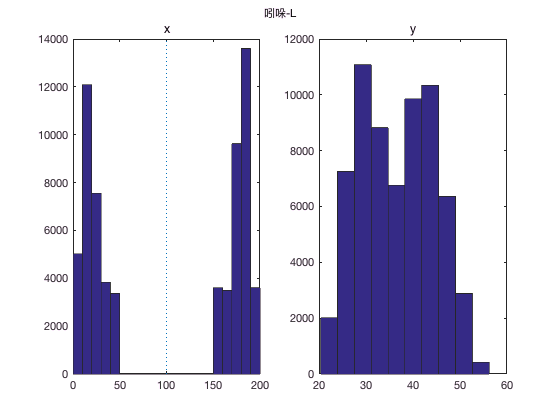

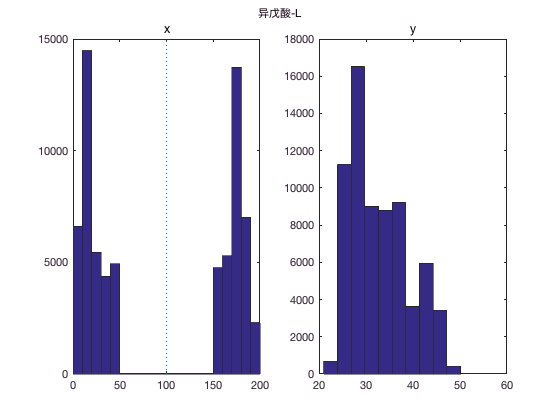

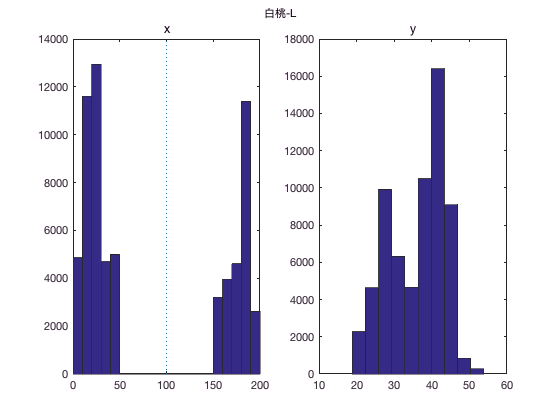

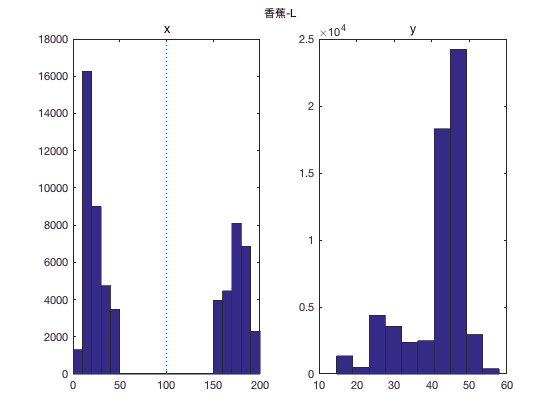

interval=10;
timeint1=0;%start minute
timeint2=30;%stop minute
p1=timeint1*60*1000/40+1;
p2=timeint2*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 合并odor两个条件的（30-60）

   100   100



pvalue = 0.3699

st =     chi2stat: 0.8040
          df: 1
       edges: [0 100 200]
           O: [33015 32785]
           E: [32900 32900]


   100   100



pvalue = 2.3169e-129

st =     chi2stat: 585.5590
          df: 1
       edges: [0 100 200]
           O: [35879 29683]
           E: [32781 32781]


   100   100



pvalue = 0.0039

st =     chi2stat: 8.3324
          df: 1
       edges: [0 100 200]
           O: [28142 28831]
           E: [2.8486e+04 2.8486e+04]


   100   100



pvalue = 1.5032e-36

st =     chi2stat: 159.4354
          df: 1
       edges: [0 100 200]
           O: [31321 34562]
           E: [3.2942e+04 3.2942e+04]


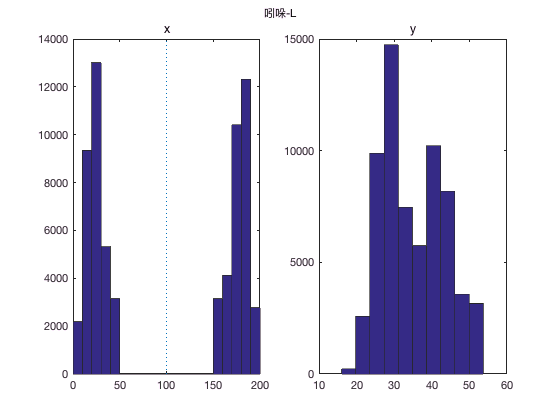

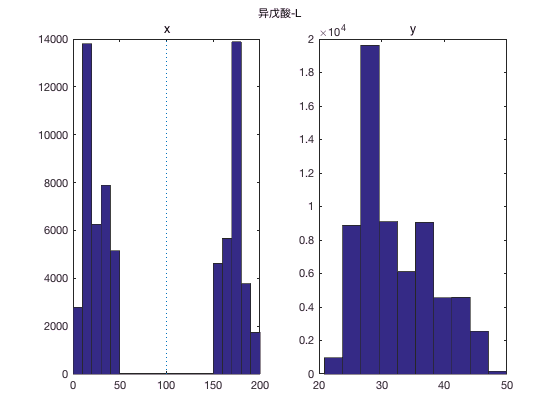

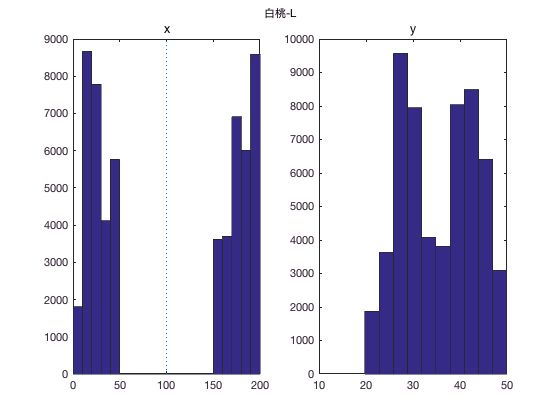

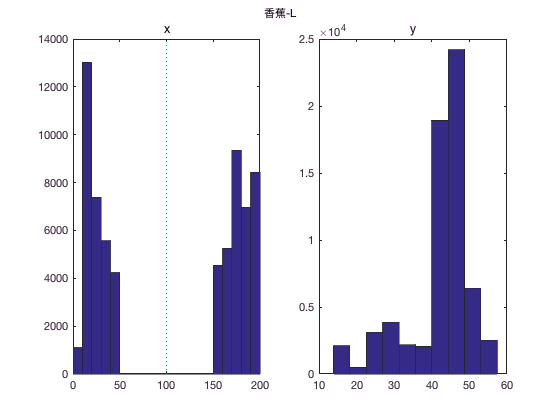

interval=10;
timeint1=30;%start minute
timeint2=60;%stop minute
p1=timeint1*60*1000/40+1;
p2=timeint2*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-20201112


-------------


100-100


       30826       14174
       31718       13282
        2641         792



  128.6124



   1.1808e-28



-------------


吲哚-R-20201110


-------------


100-100


       31524       13476
       31484       13516
         267         378



  248.8454



   9.2028e-55



-------------


异戊酸-L-20201109


-------------


100-100


       32195       12805
       29717       15283
         218         302



  490.3225



  3.3715e-107



-------------


异戊酸-R-20201106


-------------


100-100


       32543       12457
       29615       15385
        2135         756



  477.1441



  2.4518e-104



-------------


白桃-L-20201103


-------------


100-100


       28908       16092
       25217       19783
        1391          42



   1.4412e+03



  1.1105e-313



-------------


白桃-R-20201102


-------------


100-100


       22585       22415
       26869       18131
        1788         865



  986.4689



  6.1802e-215



-------------


香蕉-L-20201105


-------------


100-100


       33452       11547
       32318       12682
        2288        1539



  397.4270



   5.0099e-87



-------------


香蕉-R-20201104


-------------


100-100


       26165       18835
       31726       13274
         194           0



   1.6062e+03



     0



-------------


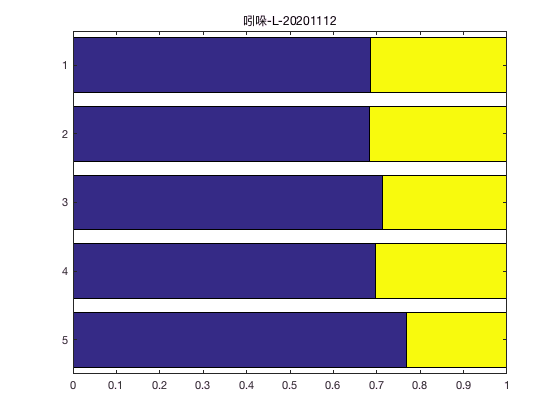

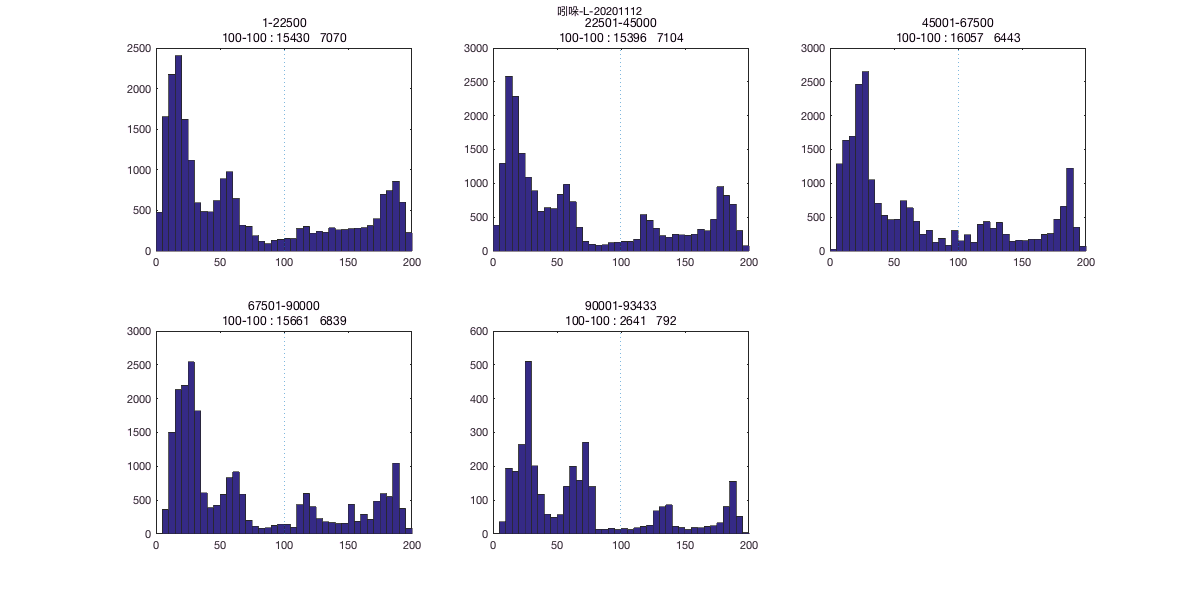

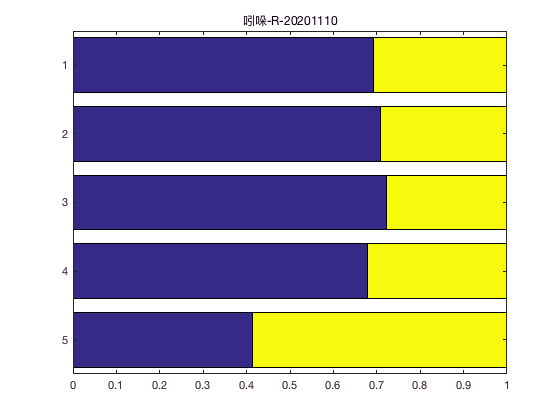

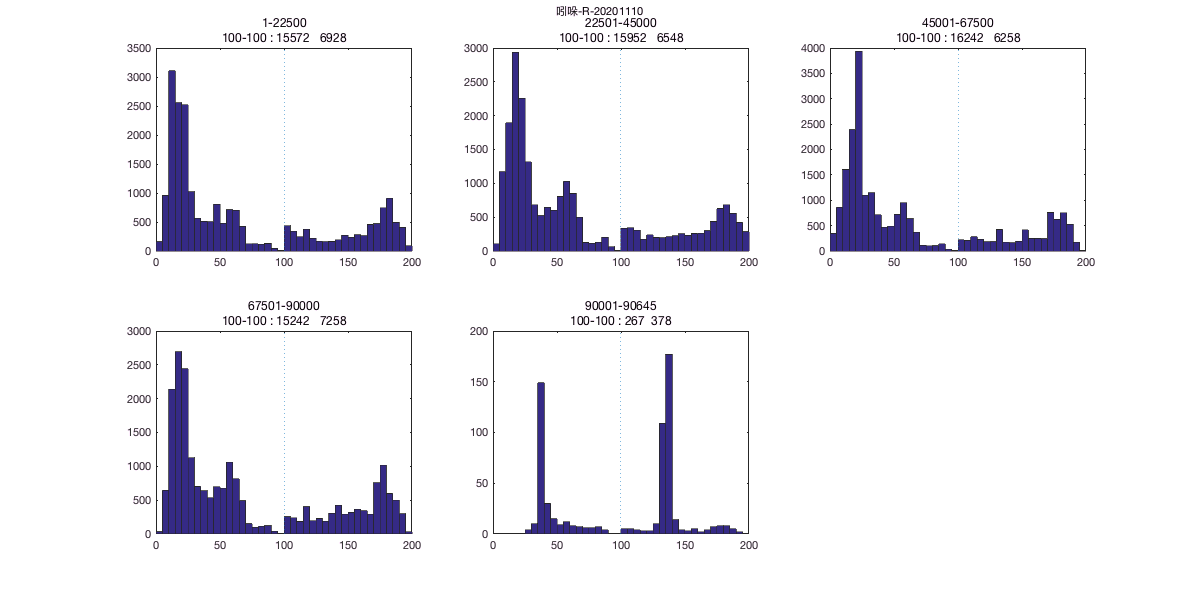

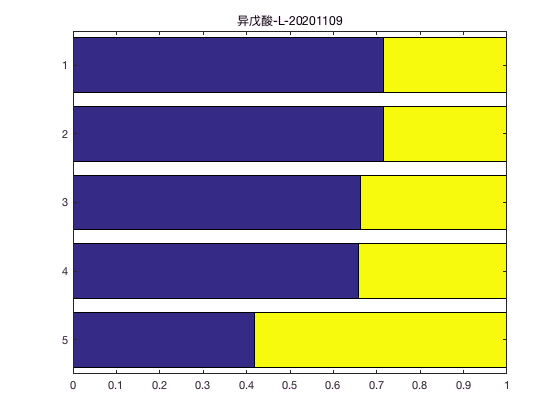

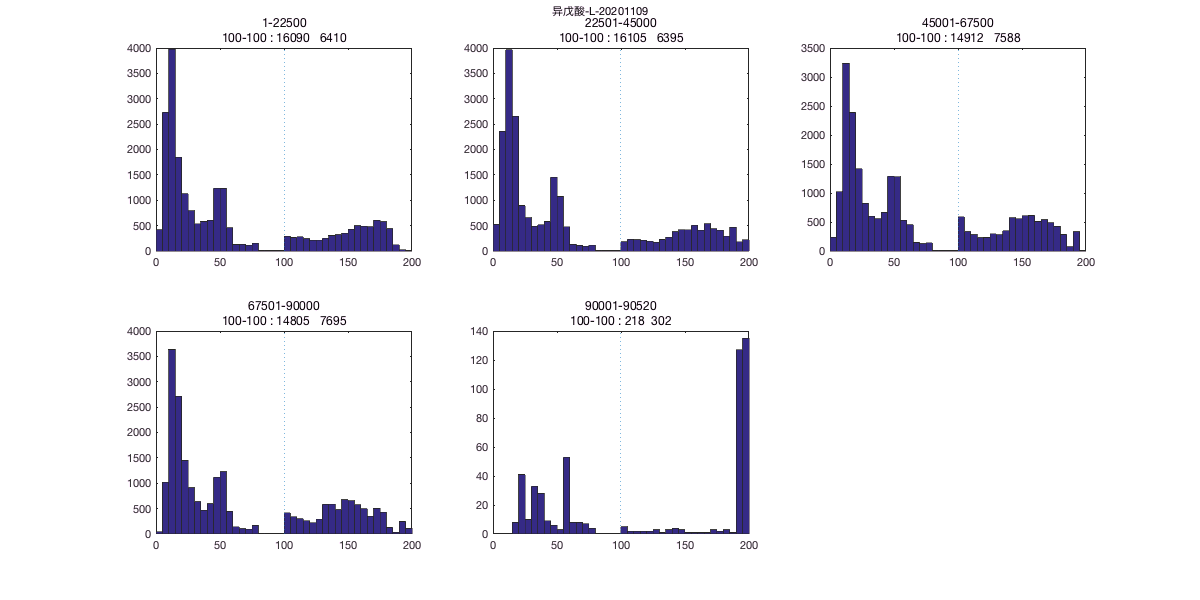

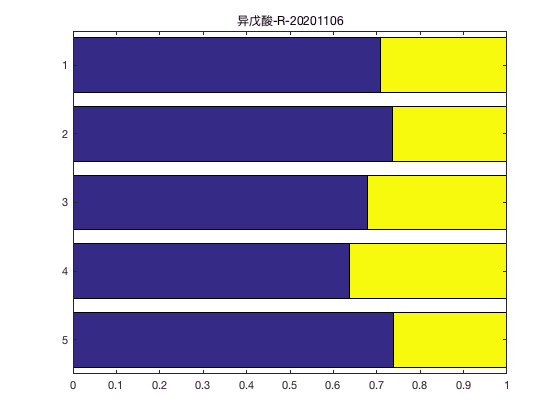

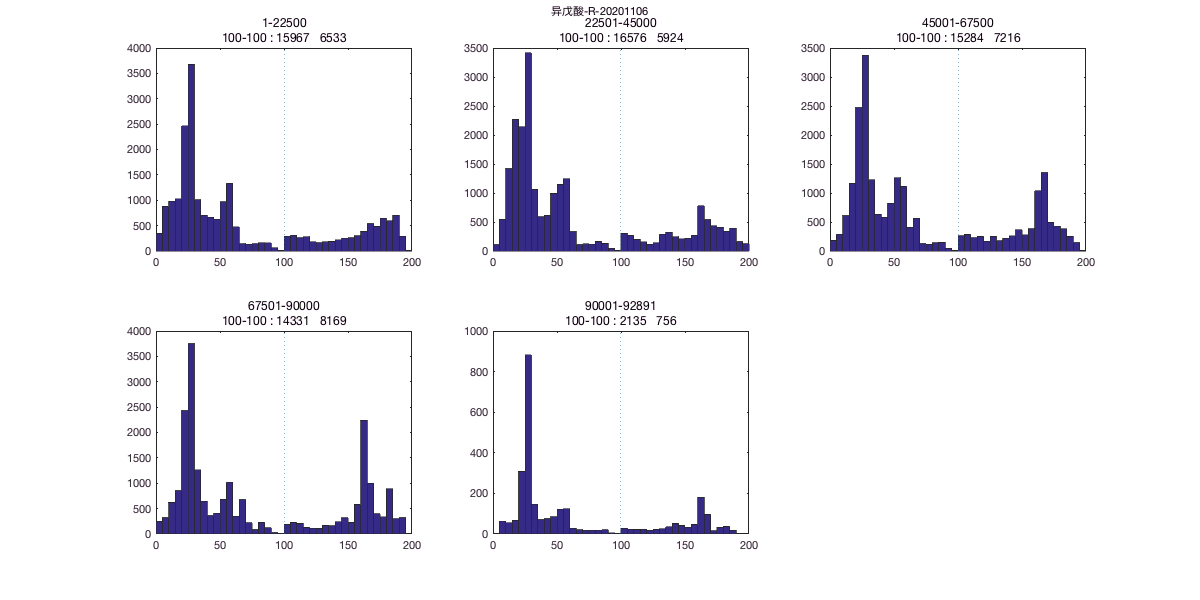

timeint=30;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);

    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0%:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})  
    end
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end

## 分时段的分布直方图(merge left and right)

timeint=15;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);

    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0%:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})  
    end
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end

吲哚-L-20201112


-------------


100-100


       15430        7070
       15396        7104
       16057        6443
       15661        6839
        2641         792



  145.2555



   2.1146e-30



-------------


吲哚-R-20201110


-------------


100-100


       15572        6928
       15952        6548
       16242        6258
       15242        7258
         267         378



  369.5006



   1.0787e-78



-------------


异戊酸-L-20201109


-------------


100-100


       16090        6410
       16105        6395
       14912        7588
       14805        7695
         218         302



  491.5276



  4.5542e-105



-------------


异戊酸-R-20201106


-------------


100-100


       15967        6533
       16576        5924
       15284        7216
       14331        8169
        2135         756



  610.5381



  8.1177e-131



-------------


白桃-L-20201103


-------------


100-100


       14875        7625
       14033        8467
       12321       10179
       12896        9604
        1391          42



   1.5381e+03



     0



-------------


白桃-R-20201102


-------------


100-100


       11163       11337
       11422       11078
       13759        8741
       13110        9390
        1788         865



   1.0304e+03



  9.3688e-222



-------------


香蕉-L-20201105


-------------


100-100


       16085        6415
       17367        5132
       17776        4724
       14542        7958
        2288        1539



   1.7477e+03



     0



-------------


香蕉-R-20201104


-------------


100-100


       13495        9005
       12670        9830
       14809        7691
       16917        5583
         194           0



   2.1029e+03



     0



-------------
